## ROUTE MAPPING

% Get coordinates of Mawson Station
Mawson_coords = scarloc('mawson station');
Spatial_res = 1;
% Create the map figure
figure('Position', [100, 100, 1200, 800]);
% Plot the map with Mawson Station and bedmachine data
mapzoomps(Mawson_coords(1)-0.4, Mawson_coords(2), 'size', [100 100], 'frame', 'off');
hold on;
scatterps(Mawson_coords(1), Mawson_coords(2), 10,'Marker', 'd', 'MarkerFaceColor', 'r');
scarlabel('Mawson');
title('Step 1: Select the waypoints along the route');
box on;
% Customize the plot as needed
scalebarps;
% Plot bedmachine data
[bed,lat,lon] = bedmachine_data('bed',xlim,ylim,'geo');
pcolorps(lat, lon, bed);
cmocean('grey')       % optional colormap
bedmachine('surface','contour',0:100:5000);
cb = colorbar;
ylabel(cb,'elevation wrt geoid (m)');
bedmachine('coast','y');
mapzoomps('nw','frame','off');
view([-90, 90]);
hold off;
disp('Select waypoints on the map. Press enter when done :)');

Select waypoints on the map. Press enter when done :)


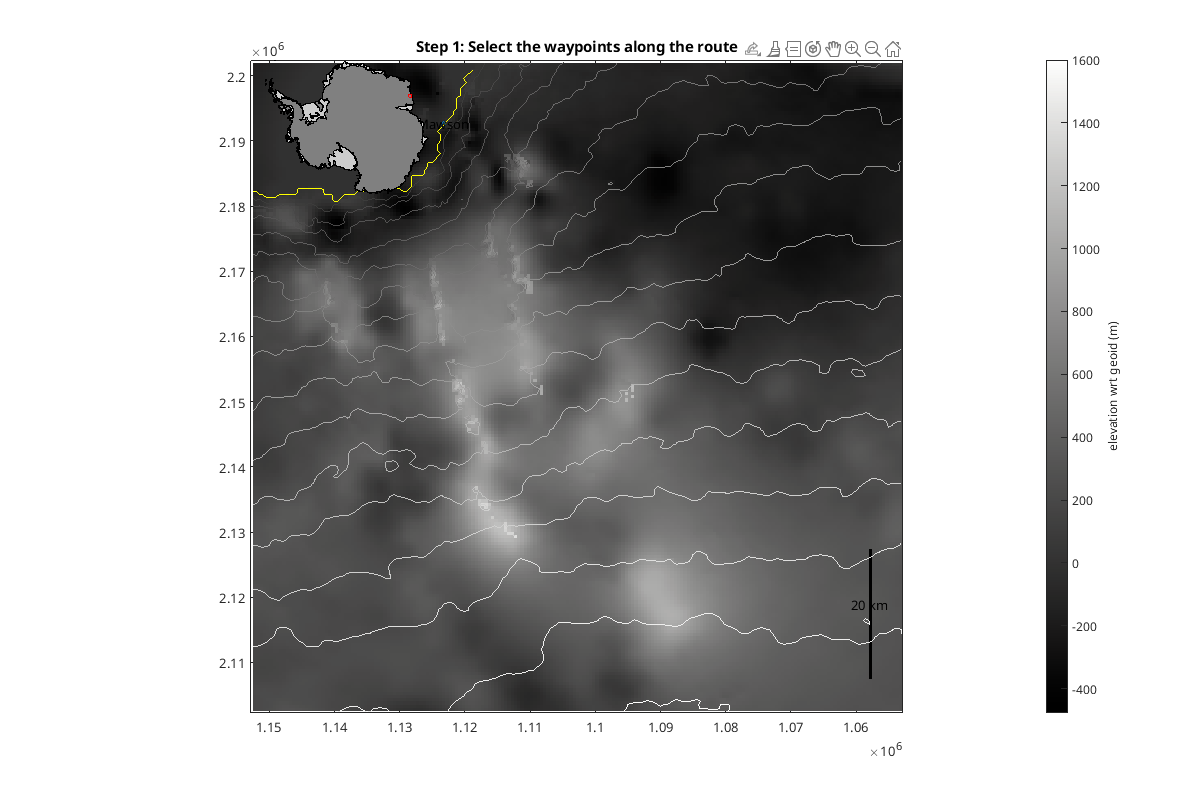

[lat,lon] = coord;

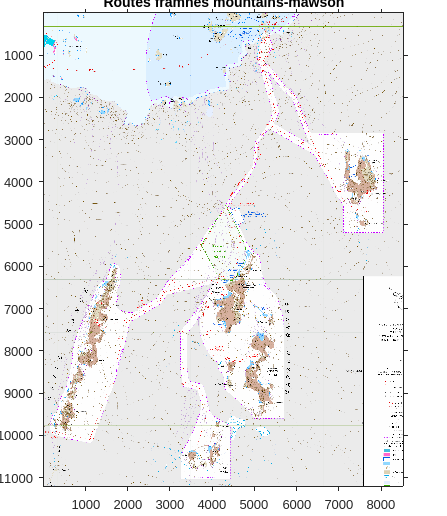


% Open the map
figure;
image = imread('Framnes_mapping.tif'); % Specify the path to your PNG picture
imshow(image);
title('Routes framnes mountains-mawson');

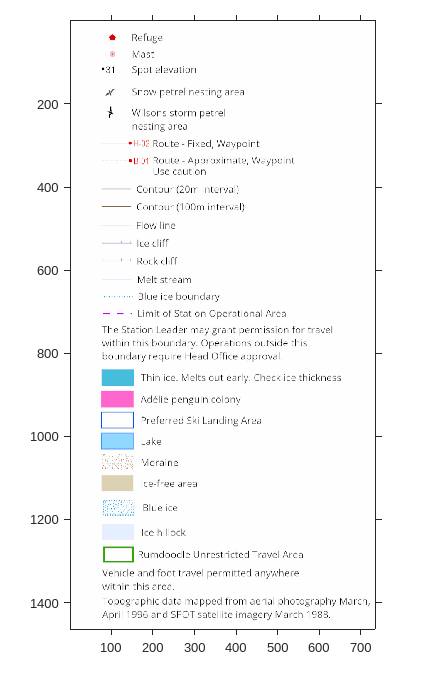


% Create another figure for the legend
figure;
legend = imread('Legend.png');
imshow(legend);


% Assign start and end points
startlat = lat(1);
startlon = lon(1);
endlat = lat(end);
endlon = lon(end);
intermediatewaypoints = [lat(2:end-1) lon(2:end-1)];
waypoints = [startlat startlon; intermediatewaypoints; endlat endlon];
[lati,loni] = pspath([startlat endlat],[startlon endlon],Spatial_res);  %gives interpolated points between the specified waypoints
linpath = [lati ; loni]';       
path = [startlat,startlon];

% Initialize cell arrays to store latitude and longitude
path_lat = startlat;
path_lon = startlon;

for k = 1:height(waypoints)
    if k < height(waypoints)
        [interlat, interlon] = pspath([waypoints(k,1) waypoints(k+1,1)], [waypoints(k,2) waypoints(k+1,2)], Spatial_res);
        
        % Append new latitude and longitude values
        path_lat = [path_lat; interlat'];
        path_lon = [path_lon; interlon'];
    end
end

% Concatenate latitude and longitude arrays
path = [path_lat, path_lon];

d = pathdistps(path(:,1)', path(:,2)', 'km')';
z = bedmachine_interp('surface', path(:,1)', path(:,2)')';

% Convert distance to meters
d_meters = d*1000;  % Convert kilometers to meters

% Calculate slope (gradient) using finite differences
dz = diff(z);  % Calculate difference in elevation
dd = diff(d_meters);  % Calculate difference in distance (in meters)
slope = dz ./ dd;  % Calculate slope


## SLICER FUNCTION AND VELOCITY PROFILER

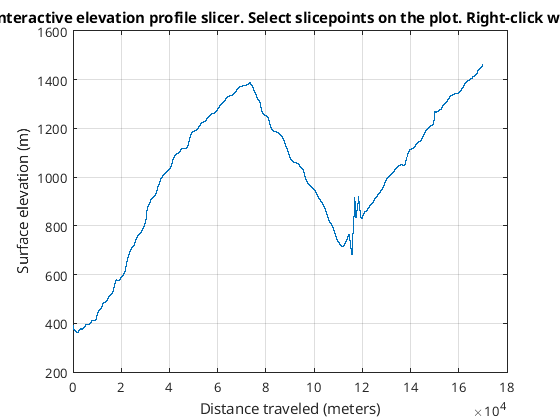

% Subplot 4: Interactive Elevation Profile Slicer
figure
plot(d_meters, z)
xlabel 'Distance traveled (meters)'
ylabel 'Surface elevation (m)'
grid on

title('Step 2: Interactive elevation profile slicer. Select slicepoints on the plot. Right-click when done :)');
[slicepoints_x, ~] = ginput();

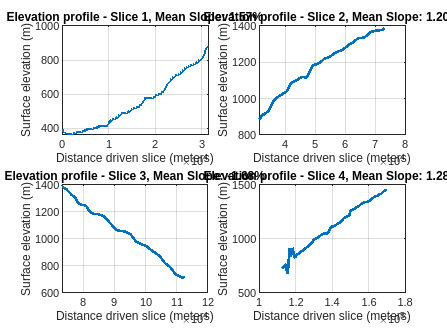

endslice_x = d_meters(end);
endslice_y = z(end);

num_slices = length(slicepoints_x) + 1;

% Calculate the number of rows and columns for the subplot grid
cols = ceil(sqrt(num_slices));
rows = ceil(num_slices / cols);

% Create a figure with a subplot grid
figure

% Cell array to store slice-specific data
slice_data = cell(num_slices, 2);
mean_slopes = zeros(num_slices, 1);  % Store slopes in a column vector
for i = 1:num_slices
    if i == 1
        % for the first slice, start from the real distance
        start_distance = 0;
    else
        % for subsequent slices, start from the end of the previous slice
        start_distance = slice_data{i-1, 1}(end);
    end
    
    % handle the last slice differently
    if i == num_slices
        end_distance = endslice_x;
    else
        end_distance = slicepoints_x(i);
    end
    
    % find indices corresponding to the selected slice
    [~, start_index] = min(abs(d_meters - start_distance));
    [~, end_index] = min(abs(d_meters - end_distance));

    % Extract the elevation and distance data for the slice
    slice_data{i, 1} = d_meters(start_index:end_index);
    slice_data{i, 2} = z(start_index:end_index);

    % adjust distance to start from the real distance
    slice_data{i, 1} = slice_data{i, 1} - slice_data{i, 1}(1) + start_distance;

    % calculate the mean slope for the slice in percentage
    elevation_change = slice_data{i, 2}(end) - slice_data{i, 2}(1);
    distance_driven = slice_data{i, 1}(end) - slice_data{i, 1}(1);
    mean_slope = (elevation_change / distance_driven) * 100;
    mean_slopes(i) = mean_slope;  % Store mean slope in the column vector
    
    % calculate the subplot index based on the current iteration
    subplot(rows, cols, i);
    plot(slice_data{i, 1}, slice_data{i, 2}, 'LineWidth', 2);
    xlabel 'Distance driven slice (meters)'
    ylabel 'Surface elevation (m)'
    title(['Elevation profile - Slice ', num2str(i), ', Mean Slope: ', num2str(mean_slope, '%.2f'), '%']);
    grid on
end


slice_velocities = zeros(1, num_slices);
for i = 1:num_slices
    % prompt the user to enter the velocity profiles per slice
    prompt = ['Enter velocity for Slice ', num2str(i), ' (in km/h): '];
    slice_velocities(i) = input(prompt);
end


## timesim calcs

clear slice_times
slice_times = zeros(1, num_slices);
% ugly ass coding sorry
total_travel_time = 0;
for i = 1:num_slices
    distance_driven = slice_data{i, 1}(end) - slice_data{i, 1}(1);
    travel_time = distance_driven / slice_velocities(i);
    slice_times(i) = travel_time;
    total_travel_time = total_travel_time + travel_time;
end
time_vector = (1:1:total_travel_time+2)';
vel_times = ones(length(time_vector), 1);
slope_times = ones(length(time_vector), 1);

current_time = 0;
for i = 1:num_slices
    slice_duration = ceil(slice_times(i));
    slice_vel = slice_velocities(i);
    slice_slope = mean_slopes(i)
    for j = 1:slice_duration
        vel_times(current_time + j) = slice_vel;
        slope_times(current_time + j) = slice_slope;
    end
    
    % Update the current time
    current_time = current_time + slice_duration;
    vel_times = vel_times(3:1:length(vel_times));
    slope_times = slope_times(3:1:length(slope_times));
end

slice_slope = 1.5732

slice_slope = 1.2044

slice_slope = -1.6819

slice_slope = 1.2801

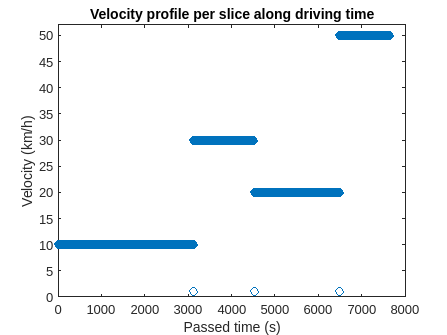

velocity_profile = [time_vector, vel_times];
slope_profile = [time_vector, slope_times];
figure;
plot(time_vector,vel_times,'o')
ylim([0 max(slice_velocities)+2]);
ylabel('Velocity (km/h)');
xlabel('Passed time (s)');
title('Velocity profile per slice along driving time')


% Calculate total change in elevation
total_change_elevation = z(end) - z(1);

## Simulation parameters

T_start = 0.0;           % Simulation start time
T_stop = time_vector(end);  % Simulation end time (assuming time_vector is defined)
T_step = 1;               % Simulation timestep in seconds
Crr = 0.15;                % Rolling friction coefficient

Mass_values = [400 500 600];        % Vehicle total mass
Battmassfrac = 0.3;       % Fraction of the total mass allocated to the battery

g = 9.81;                 % Gravitational acceleration
Batt_mdens_values = [80 150 200 250 300 400]; %Energy density of diff. configs (Wh/kg)
Packingfactor = 2;        % Offset to the energy density
Aux_power = 200; %Power draw used for non-drivetrain equipment (Watts)
kwh_used_values, SoC_values = zeros(numel(Mass_values)); % Preallocate matrix for efficiency

kwh_used_values =     3.2443         0         0
    4.0040         0         0
    4.7637         0         0



for mass_idx = 1:numel(Mass_values)
    Mass = Mass_values(mass_idx);
    
    for batt_dens_idx = 1:numel(Batt_mdens_values)
        Batt_mdens = Batt_mdens_values(batt_dens_idx);
        
        % Run the simulation with current mass and battery mass fraction
        simOut = sim("Mass_est.slx", 'ExternalInput', num2str(Mass), 'ExternalInput', num2str(Batt_mdens));    
        
        % Store the simulation result
        kwh_used_values(mass_idx) = simOut.simout(end);
        SoC_values(batt_dens_idx,mass_idx) = simOut.simout1(end);
    
        disp(['Simulation completed for mass = ', num2str(Mass), ', Batt_mdens = ', num2str(Batt_mdens)]);
    end
end

Simulation completed for mass = 400, Batt_mdens = 80
Simulation completed for mass = 400, Batt_mdens = 150
Simulation completed for mass = 400, Batt_mdens = 200
Simulation completed for mass = 400, Batt_mdens = 250
Simulation completed for mass = 400, Batt_mdens = 300
Simulation completed for mass = 400, Batt_mdens = 400
Simulation completed for mass = 500, Batt_mdens = 80
Simulation completed for mass = 500, Batt_mdens = 150
Simulation completed for mass = 500, Batt_mdens = 200
Simulation completed for mass = 500, Batt_mdens = 250
Simulation completed for mass = 500, Batt_mdens = 300
Simulation completed for mass = 500, Batt_mdens = 400
Simulation completed for mass = 600, Batt_mdens = 80
Simulation completed for mass = 600, Batt_mdens = 150
Simulation completed for mass = 600, Batt_mdens = 200
Simulation completed for mass = 600, Batt_mdens = 250
Simulation completed for mass = 600, Batt_mdens = 300
Simulation completed for mass = 600, Batt_mdens = 400


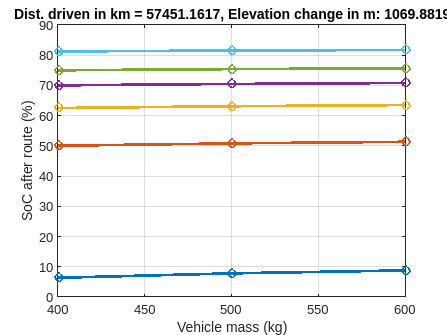


%% Plotting stuff

total_change_elevation = z(end) - z(1);
figure;

plot(Mass_values, SoC_values, 'o-', 'LineWidth', 2);
xlabel('Vehicle mass (kg)');
ylabel('SoC after route (%)');
legend(num2str(Batt_mdens(1)));
grid on
title(['Dist. driven in km = ', num2str(distance_driven), ', Elevation change in m: ', num2str(total_change_elevation)]);